# **Orientation Stats** · Getting started

*If you use this toolbox, please cite: *[*Camouflage Detection & Signal Discrimination: Theory, Methods & Experiments*](http://dx.doi.org/10.13140/RG.2.2.10585.80487)*.*

*Bugs/questions/comments to abhranil.das@utexas.edu.*

*Abhranil Das & Wilson Geisler, Center for Perceptual Systems, University of Texas at Austin*

For more info and help, type

doc orientation_stats

and to know more about how these are mathematically computed, see the ReadMe for the toolbox, or on [github](https://github.com/abhranildas/orientation_stats).

Some line segments with random orientations and lengths:

n_lines=10;
dist_mean=unifrnd(0,2*pi); dist_sd=unifrnd(0,2*pi);
thetas=normrnd(dist_mean,dist_sd,[n_lines 1])

thetas =     5.1489
   -0.2160
    4.3293
    9.5130
    4.8907
    4.7158
    2.3349
    4.4942
    5.3021
    5.8978


Compute vector-avg. orientation and its length, and sd around mean:

[theta_m,theta_s,length_m]=orientation_stats(thetas)

theta_m = -1.0921

theta_s = 0.6558

length_m = 0.3509

Now specify lengths of the oriented line segments, and compute the same statistics weighted by these lengths:

lengths=abs(normrnd(1,.5,[n_lines 1]))

lengths =     0.8136
    0.8818
    2.0118
    0.1292
    2.1147
    1.1688
    1.5000
    0.1679
    0.7050
    0.8610


[theta_m,theta_s,length_m]=orientation_stats(thetas,lengths)

theta_m = -1.2527

theta_s = 0.6935

length_m = 0.5050

Plot the line segments (black lines), the mean orientation (red line), and the sd around it (red arcs):

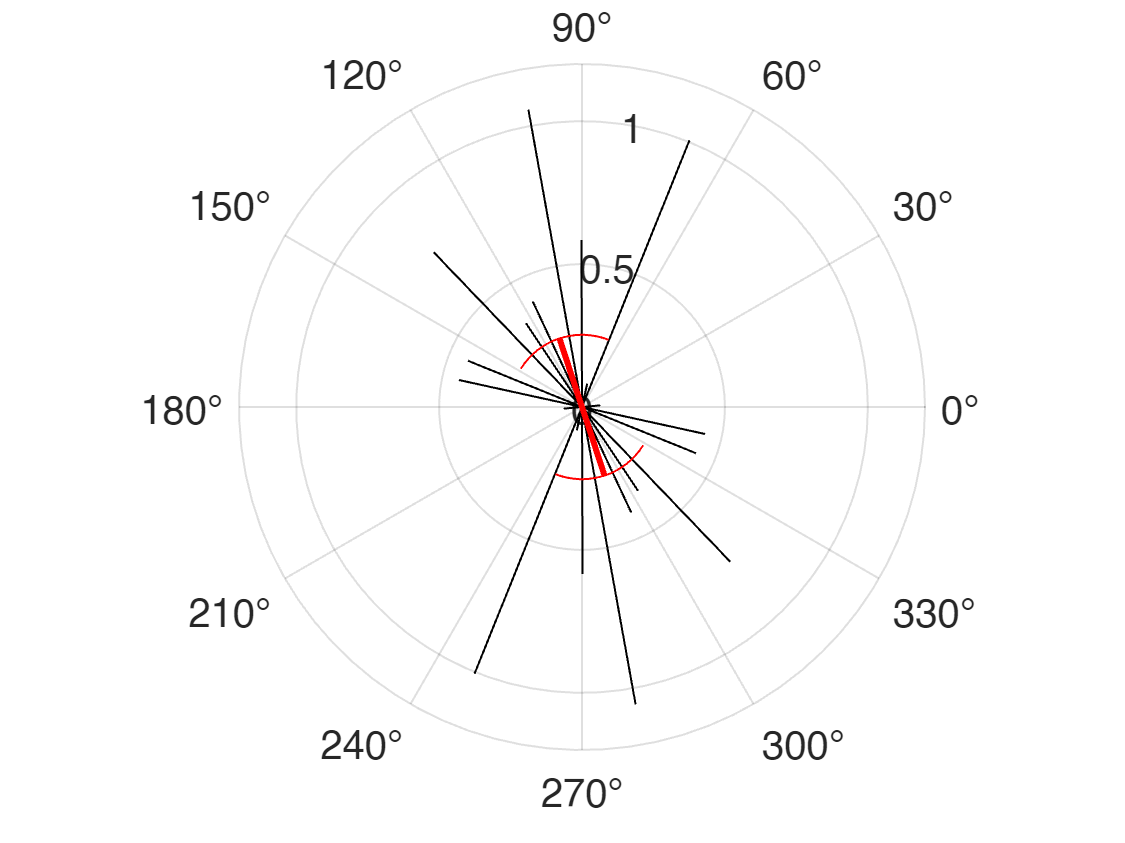

polarplot(thetas(1)*[1 1],lengths(1)/2*[-1 1],'-','color','k')
hold on
for i=2:n_lines
    polarplot(thetas(i)*[1 1],lengths(i)/2*[-1 1],'-','color','k')
end

polarplot(theta_m*[1 1],length_m/2*[-1 1],'-r','linewidth',1.5)

theta_arc=linspace(theta_m-theta_s,theta_m+theta_s,100);
rho=length_m/2*ones([1 length(theta_arc)]);
polarplot(theta_arc,rho,'-r')
polarplot(theta_arc,-rho,'-r')